# 测量数据预处理

% clear;
% clc;

folder_path = "D:\Research\experiments\ids results mat";
file_path = "20240601 IDS\XB_Y1500_A3J80.mat";
sample_rate = 100000;

data0 = load(fullfile(folder_path,file_path));

% data0.Displacement = data0.Displacement(1:100:end);
displacement = transpose(data0.Displacement);
time = transpose((0:1:(length(displacement) - 1))/sample_rate);
% data = timetable(time,data0.Displacement,'VariableNames',{'Displacement'});
data = timetable(transpose(data0.Displacement),'VariableNames',{'Displacement'},'SampleRate',sample_rate);
clear data0


## 降采样

% data_downsample = resample(data,1,10);
% % displacement_downsample = resample(displacement,1,10);
% cal_motion(data_downsample);

## 低通滤波去噪

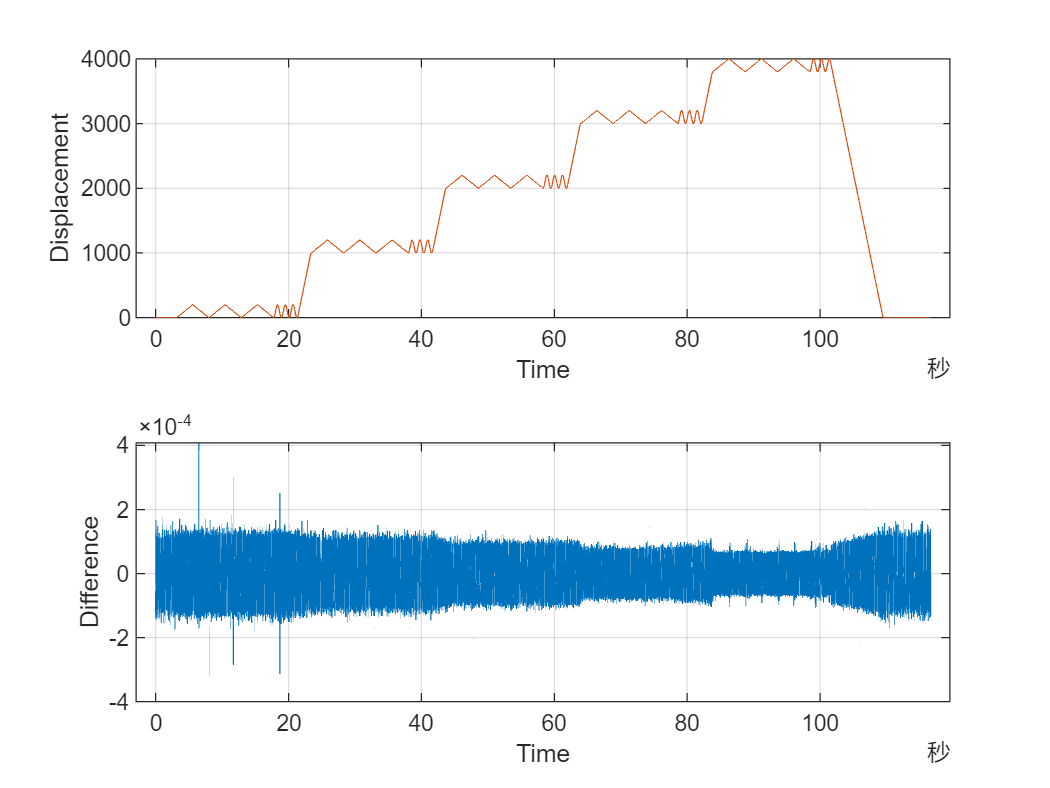

denoise_method = 'WT';
switch denoise_method
    case 'Uniform'
    case 'Gaussian'
    case 'FIR'
        fir_order = 1;
        fir_freq_range = [];
        fir_filter = fir1(fir_order,fir_freq_range);
        freqz(fir_filter);
        data_denoise = filter(fir_filter,1,data);
    case 'WT'
        % either app or functions
        data_denoise = wdenoise(data,5,Wavelet='sym4', ...
            DenoisingMethod='Bayes',ThresholdRule='Soft', ...
            NoiseEstimate='LevelIndependent');
end
figure('Name','Effect of denoising');
tiledlayout(2,1);
nexttile;
plot(data.Time,data.Displacement);
hold on;
plot(data_denoise.rowtimes,data_denoise.Displacement);
grid on;
xlabel('Time');
ylabel('Displacement');
nexttile;
plot(data.Time,data_denoise.Displacement - data.Displacement);
grid on;
xlabel('Time');
ylabel('Difference');

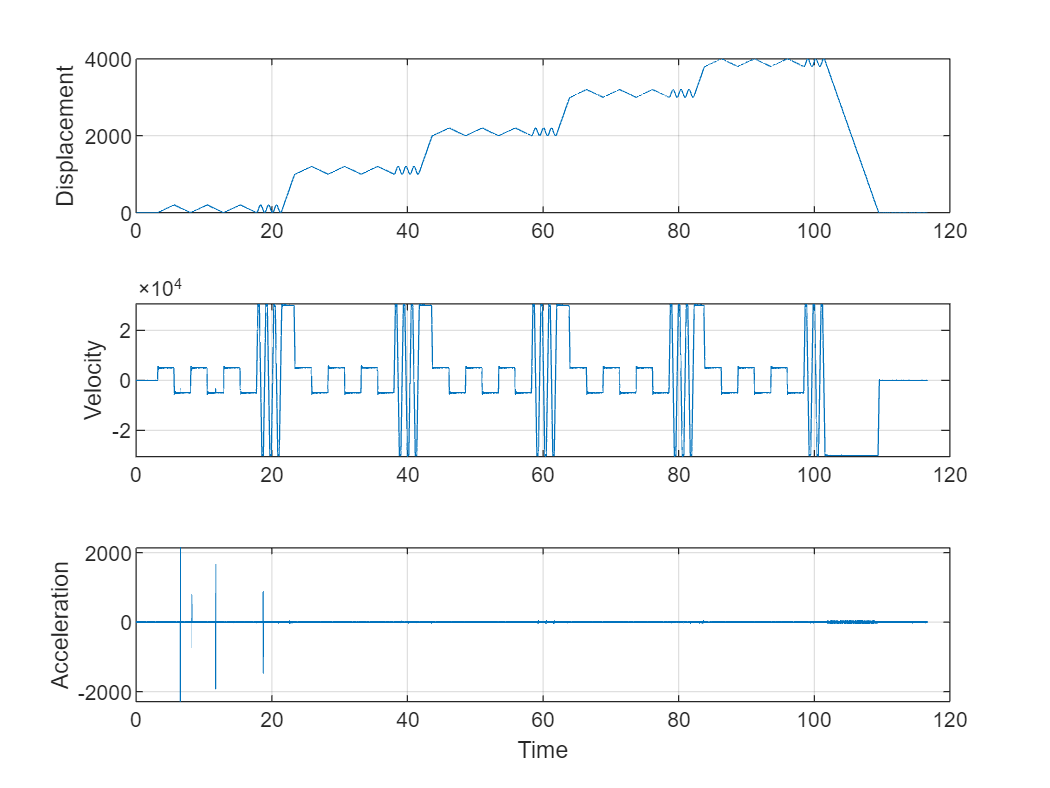

% subplot(3,1,1);
% plot(time,displacement);
% title('Original Time Series');
% grid on;
% subplot(3,1,2);
% plot(time,displacement_denoise);
% title('Denoised Time Series');
% grid on;
% subplot(3,1,3);
% plot(time,displacement_denoise - displacement);
% title('Noise Time Series');
% grid on;

% cal_motion(time,displacement);
cal_motion(data_denoise);

cal_motion(time,displacement);

函数或变量 'displacement1' 无法识别。

## 计算运动量

function [time_velo,velo,time_accel,accel,time_jerk,jerk] = cal_motion(varargin)
if length(varargin) == 1
    time = seconds(varargin{1}.rowtimes);
    displacement = varargin{1}.Displacement;
else
    time = varargin{1};
    displacement = varargin{2};
end
% 计算速度和对应时间向量
velo = 60*diff(displacement)./diff(time);
time_velo = time(1:end - 1) + diff(time)/2;

% 计算加速度和对应的时间向量
accel = diff(velo)./diff(time_velo)./60000;
time_accel = time_velo(1:end - 1) + diff(time_velo)/2;

% 计算跃度和对应的时间向量
jerk = diff(accel)./diff(time_accel);
time_jerk = time_accel(1:end - 1) + diff(time_accel)/2;

figure('Name','运动量');
tiledlayout(3,1);
nexttile;
plot(time,displacement);
ylabel('Displacement');
grid on;
nexttile;
plot(time_velo,velo);
ylabel('Velocity');
grid on;
nexttile;
plot(time_accel,accel);
ylabel('Acceleration');
grid on;
xlabel('Time');
end